# Figure 2.6

Nonlinear solvers are contained in the directory `source/continuation` and one may create the images in Figure 2.6 either by using the high-level continuation commands or by using the lower level solver commands directly. Here, I do things both ways.

## High-level continuation commands

Running these commands will create new directories beneath the `data/` directory.

### Dumbbell example

First, set up the folder to house the solutions and the quantum graph.

tag='dumbbell';
Phi=quantumGraphFromTemplate(tag);
dataDir = makeContinuationDirectory(Phi,tag);

Created directory data/dumbbell/168.


Define the nonlinear function used to define the standing waves. Note that by default $f(z)  = 2z^3$, so that the simpler one-liner

will have the same effect.

syms z  
f = 2*z^3;
saveNLSFunctionsGraph(dataDir,Phi,f);

Solve the nonlinear standing wave equation from an initial guess with a bump on edge $\mathtt{e}_2$.

edges=2;
signs=1;
Lambda0=-1;
filenumber=saveHighFrequencyStandingWave(dataDir,Lambda0,edges,signs);

File saved to data/dumbbell/168/savedFunction.001.
File number is 1. 


Now, the solution is stored as file `savedFunction.001`

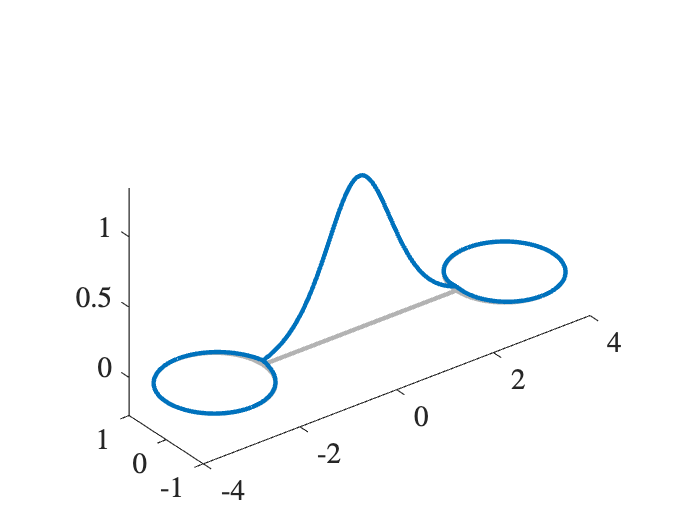

vec = load(fullfile(dataDir,"savedFunction.001"));
Phi.plot(vec);

### Spiderweb example

tag = 'spiderWeb';
Phi=quantumGraphFromTemplate(tag);
dataDir = makeContinuationDirectory(Phi,tag);

Created directory data/spiderWeb/007.


saveNLSFunctionsGraph(dataDir,Phi);

To use the `saveHighFrequencyStandingWaveGraphical program`, you need to specify the frequency and the center of the bump

Lambda0=-1;
x0 = [0 0];
fileNumber=saveHighFrequencyStandingWaveGraphical(dataDir,Lambda0,x0);

File saved to data/spiderWeb/007/savedFunction.001.
File number is 1. 


Load the saved solution and plot it

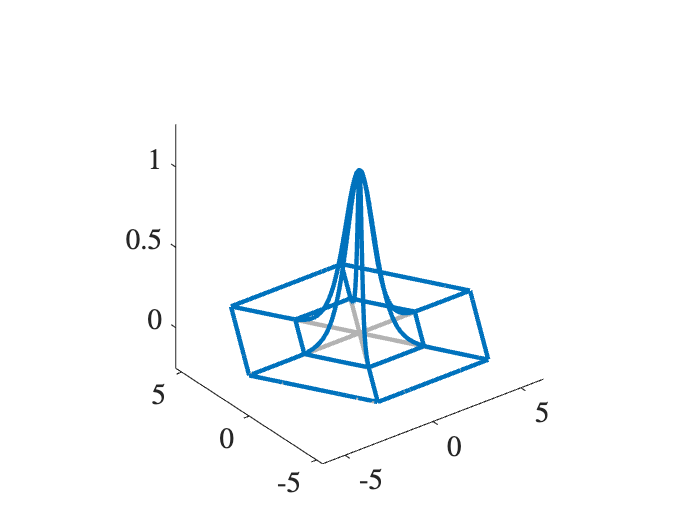

vec = load(fullfile(dataDir,"savedFunction.001"));
Phi.plot(vec);

## Low-level solver commands.

We repeat the calculations using lower-level commands and Chebyshev discretization.

### Dumbbell

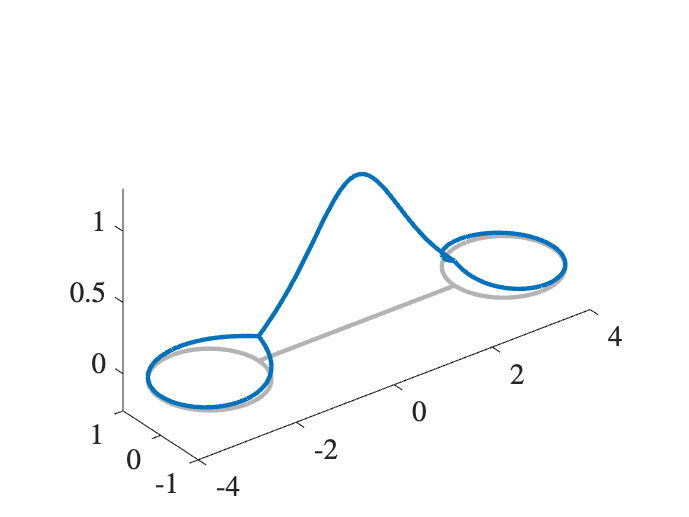

Phi1=quantumGraphFromTemplate('dumbbell');%,'Discretization','Chebyshev');
Lambda0=-1;
L = Phi1.L(2); % The length of the second edge
PhiGuess = Phi1.applyFunctionsToAllEdges({0,@(x)sech(x-L/2),0});
fcns=getNLSFunctionsGraph(Phi1);
myF=@(z) fcns.f(z,Lambda0);
myMatrix = @(u) fcns.fLinMatrix(u,Lambda0);
tol=1e-6;
[PhiColumn,~,~]=solveNewton(PhiGuess,myF,myMatrix,tol);
Phi1.plot(PhiColumn);

### Spiderweb

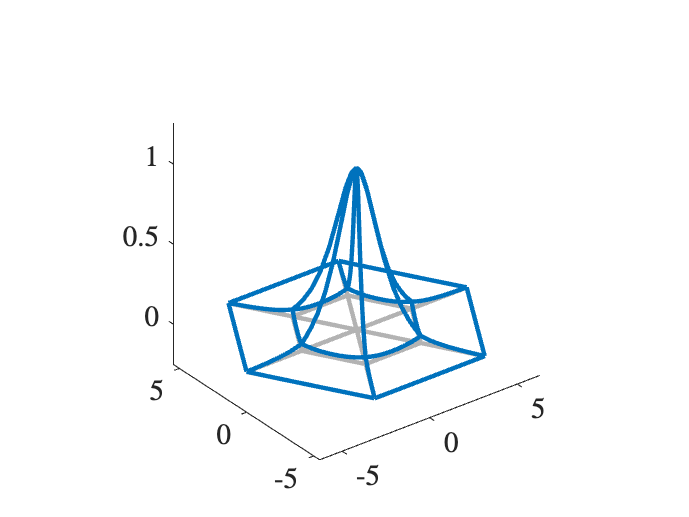

Phi2=quantumGraphFromTemplate('spiderWeb','Discretization','Chebyshev');
Lambda0=-1;
PhiGuess = Phi2.applyGraphicalFunction(@(x,y)sech(sqrt(x.^2+y.^2)));
fcns=getNLSFunctionsGraph(Phi2);
myF=@(z) fcns.f(z,Lambda0);
myMatrix = @(u) fcns.fLinMatrix(u,Lambda0);
tol = 1e-6;
[PhiColumn,~,~]=solveNewton(PhiGuess,myF,myMatrix,tol);
Phi2.plot(PhiColumn);